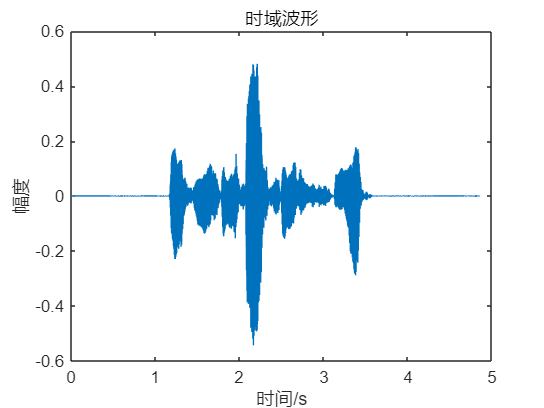

% 清除工作区变量和命令窗口
clc;clear;

% 读取音频文件
% y: 音频数据（振幅值）
% Fs: 采样频率（每秒采样点数）
[y, Fs] = audioread('dspx1.wav');

% 绘制时域波形
t = (0:length(y)-1) / Fs;  % 将采样点序号转换为实际时间
figure;
plot(t, y);
title('时域波形');
xlabel('时间/s');
ylabel('幅度');

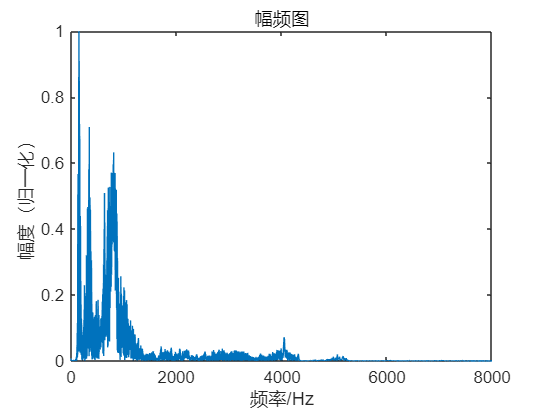


% 绘制幅频图
figure;
N = length(y);          % 获取信号总长度
Y0 = fft(y);           % 对信号进行快速傅里叶变换
f = (0:N-1)*Fs/N;      % 计算频率轴
Y = abs(Y0)/abs(max(Y0));  % 计算归一化幅度谱
plot(f, Y);
title('幅频图');
xlabel('频率/Hz');
ylabel('幅度（归一化）');
xlim([0,8000]);        % 限制显示频率范围为0-8000Hz